**The numeric simulations considering noised chi. **

**For Figure S1b.**

%%%initialization
rng('shuffle');
total=4e6;
muphi=zeros(total,6);


N=4e3;
mR=1.4e6;%Da


i=1;
while i~=0
CV_keff=1.97;
mean_keff=48000;%Da/min
sigma_knorm=sqrt(log(1+CV_keff^2));
mean_knorm=log(mean_keff)-sigma_knorm^2/2;
k_norm=mean_knorm+sigma_knorm*randn(N-1,1);
keff_oth=exp(k_norm);
keff_R=20700;%Da/min
keff=[keff_R;keff_oth];


CV_alpha=1.755436;
mean_alpha=1.1e-3;%min-1
sigma_anorm=sqrt(log(1+CV_alpha^2));
mean_anorm=log(mean_alpha)-sigma_anorm^2/2;
a_norm=mean_anorm+sigma_anorm*randn(N-1,1);
alpha_oth=exp(a_norm);
alphaR=4.83e-4;
alpha=[alphaR;alpha_oth];

temp1=corr(keff_oth,alpha_oth)    ;
if abs(temp1)>0.02
    i=0;
end
end
phi0=0.08;

%%%simulation
% Note that this simulation process is very time consuming.
% We therefore provide an example result for the following analysis.
% muphi_noise_chi.mat
chiRmax=1;
dphi=1e-3;
parfor series=1:total
   
    chiR=chiRmax*rand(1);       
    rho_xk=2*rand(1)-1;
    rho_xa=2*rand(1)-1;
    
    chi_oth=multi_cor_new(sigma_knorm, ...
        mean_knorm, ...
        k_norm, ...
        sigma_anorm, ...
        mean_anorm, ...
        a_norm, ...
        rho_xk, ...
        rho_xa, ...
        N-1, ...
        chiR);
    
    chi=[chiR;chi_oth];%theoretical value
    
    k=1;
    while k~=0
    temp1=normrnd(0,[chi/10],[N,1]);
    %generate noises where mean=0 and sigma=chi_i/10 
    chi_noi=chi+temp1;
    if isempty(chi_noi(chi_noi<0))==1
    k=0;
    chi_noi=chi_noi/sum(chi_noi);
    end
    end
    

   if min(chi_oth)<0
       continue
   end
    
    
%%%%first calculate the Ikx and Iphia without noise
    
    phi_min=phi0/(1-alphaR*mR/(keff_R*chi(1)));
    
    phi_tot=(phi_min+dphi):dphi:1;
    phi_tot=sort(phi_tot,"descend");
    
    lphi=length(phi_tot);
    for i=1:lphi
        phiR=phi_tot(i);
        mu=keff_R*(1-phi0/phiR)*chi(1)/mR-alphaR;
        fa=1-phi0/phiR;
        
        phiR_1=mR/(sum(keff.*chi*fa./(mu+alpha)));
        
        if phiR_1>=phiR
            break;
        end
        
    end
    %searching for the phR that makes muR=mu
    
    if length(i)==0
    continue
    end
    
    
    if i==lphi
    muphi(series,:)=[-1 phiR -1 chi(1) -1 alpha(1)];
    continue
    end
    
    if i==1
    muphi(series,:)=[-1 phiR -1 chi(1) -1 alpha(1)];
    continue
    end
    
    phi=keff.*chi*(phiR-phi0)./(mR*(alpha+mu));
    CV_phi=var(phi(2:N))^0.5/mean(phi(2:N));
    CV_chi=var(chi(2:N))^0.5/mean(chi(2:N));
    
    
     Ia=corr(phi(2:N),alpha(2:N))*(var(alpha(2:N))^0.5/mean(alpha(2:N)))*CV_phi;
     Ik=corr(chi(2:N),keff(2:N))*(var(keff(2:N))^0.5/mean(keff(2:N)))*CV_chi;
    

 
%%%%then calculate the phR and mu with noises
    
    phi_min=phi0/(1-alphaR*mR/(keff_R*chi_noi(1)));
    
    phi_tot=(phi_min+dphi):dphi:1;
    phi_tot=sort(phi_tot,"descend");

    
    lphi=length(phi_tot);
    for i=1:lphi
        phiR=phi_tot(i);
        mu=keff_R*(1-phi0/phiR)*chi_noi(1)/mR-alphaR;
        fa=1-phi0/phiR;
        
        phiR_1=mR/(sum(keff.*chi_noi*fa./(mu+alpha)));
        
        if phiR_1>=phiR
            break;
        end
        
    end
    %searching for the phR that makes muR=mu
    
    if length(i)==0
    continue
    end
 
    
    if i==lphi
    muphi(series,:)=[-1 phiR -1 chi(1) -1 alpha(1)];
    continue
    end
    
    if i==1
    muphi(series,:)=[-1 phiR -1 chi(1) -1 alpha(1)];
    continue
    end    
 
      
    
    
    
    muphi(series,:)=[mu phiR Ik CV_chi Ia CV_phi];

end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).



pp=find(muphi(:,1)<=0);
muphi(pp,:)=[];
pp=find(muphi(:,2)<0);
muphi(pp,:)=[];
pp=find(muphi(:,2)>1);
muphi(pp,:)=[];

%reduce size
muphi(:,4)=0;
muphi(:,6)=0;
%save("muphi_noise_chi.mat",'muphi') 

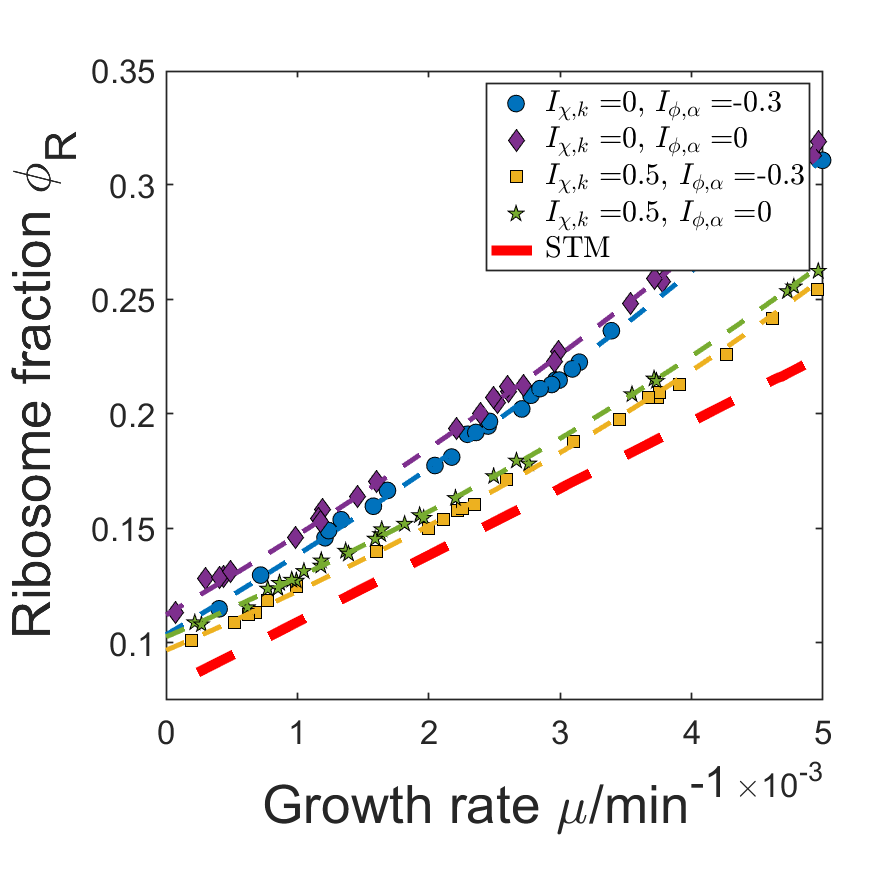

%%%plot
load muphi_noise_chi.mat

fig=figure;
set(fig,'Position',[300 100 700 700]);

ax1=axes('position', [0.19 0.2 0.75 0.72]);

p=zeros(3,3);


i_0=0;
i_1=[0 0.5 ];
%i_1=-0.5;
for Ikx=i_1
i_0=i_0+1;

j_0=0;
j_1=[-0.3 0];
%j_1=0;
for Ialpx=j_1
j_0=j_0+1;

muphi_0=muphi;


pp=find(muphi_0(:,3)<Ikx-0.02|muphi_0(:,3)>Ikx+0.02);
muphi_0(pp,:)=[];
pp=find(muphi_0(:,5)<Ialpx-0.01|muphi_0(:,5)>Ialpx+0.01);
muphi_0(pp,:)=[];
 

if i_0==1
    if j_0==1
    colors='#0072BD';
    shapes='o';
    else
    colors='#7E2F8E';
    shapes='d'; 
    end
else
    if j_0==1
    colors='#EDB120';
    shapes='s';
    else
    colors='#4DBEEE';
    shapes='p'; 
    end
end

p(i_0,j_0)=plot(muphi_0(1:60,1),muphi_0(1:60,2),shapes, ...
    "MarkerSize",10, ...
    'MarkerEdgeColor','black', ...
    'MarkerFaceColor',	colors,...
    'DisplayName',['$I_{\chi,k} = $',num2str(i_1(i_0)),', $I_{\phi,\alpha} = $',num2str(j_1(j_0))]) ;


hold on
end
end



hold on


%%% plot predications with Ikx and Iphia without noises
rng('shuffle');
total=2e5;

var_chi=zeros(1,total);

i_0=0;
i_1=[0 0.5];
for Ikx=i_1
i_0=i_0+1;

j_0=0;
j_1=[-0.3 0];
for Ialpx=j_1
j_0=j_0+1;
   


muphi_pre=IkxIak_sol_fun(total,Ikx,Ialpx,mean_keff,keff_R,mean_alpha,alphaR);
  
 

if i_0==1
    if j_0==1
    colors='#0072BD';
    else
    colors='#7E2F8E';
    end
else
    if j_0==1
    colors='#EDB120';
    else
    colors='#4DBEEE';
    end
end

plot(muphi_pre(:,1),muphi_pre(:,2),'--','LineWidth',3,'color',colors) 


hold on
end
end


%%%predication with STM
load muphi_stm.mat
p6=plot(muphi_stm(:,1),muphi_stm(:,2),'--',"LineWidth",6,'DisplayName','STM',"Color","red");

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('Growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Ribosome fraction \phi_R','interpreter','tex','FontSize',32);
axis([0 5e-3,0.0750  0.35])
hold on


legend([p(1,1) p(1,2) p(2,1) p(2,2) p6],'interpreter','Latex')
hold off

The prediction function.

function[muphi]=IkxIak_sol_fun(total,Ikx,Ialpx,mean_keff,kR,mean_alpha,alphaR)
  
muphi=zeros(total,6);



mR=1.4e6;


phi0=0.08;



   chiR=0:1/(total-1):1;
   phiR=(mR*mean_alpha + mean_keff*phi0 + Ialpx*mR*mean_alpha + Ikx*mean_keff*phi0 + chiR*kR*phi0 - chiR*mean_keff*phi0 - Ikx*chiR*mean_keff*phi0)./(mean_keff + Ikx*mean_keff + chiR*kR - alphaR*mR - chiR*mean_keff + mR*mean_alpha - Ikx*chiR*mean_keff + Ialpx*mR*mean_alpha) - (alphaR*mR - chiR*kR + mR*mean_alpha + mean_keff*phi0 - sqrt(Ialpx^2*mR^2*mean_alpha^2 - 2*Ialpx*Ikx*chiR*mR*mean_keff*mean_alpha*phi0 + 2*Ialpx*Ikx*mR*mean_keff*mean_alpha*phi0 - 2*Ialpx*alphaR*mR^2*mean_alpha - 2*Ialpx*chiR*kR*mR*mean_alpha*phi0 + 2*Ialpx*chiR*kR*mR*mean_alpha - 2*Ialpx*chiR*mR*mean_keff*mean_alpha*phi0 + 2*Ialpx*mR^2*mean_alpha^2 + 2*Ialpx*mR*mean_keff*mean_alpha*phi0 + Ikx^2*chiR.^2*mean_keff^2*phi0^2 - 2*Ikx^2*chiR*mean_keff^2*phi0^2 + Ikx^2*mean_keff^2*phi0^2 + 2*Ikx*alphaR*chiR*mR*mean_keff*phi0 - 2*Ikx*alphaR*mR*mean_keff*phi0 - 2*Ikx*chiR.^2*kR*mean_keff*phi0^2 + 2*Ikx*chiR.^2*kR*mean_keff*phi0 + 2*Ikx*chiR.^2*mean_keff^2*phi0^2 + 2*Ikx*chiR*kR*mean_keff*phi0^2 - 2*Ikx*chiR*kR*mean_keff*phi0 - 2*Ikx*chiR*mR*mean_keff*mean_alpha*phi0 - 4*Ikx*chiR*mean_keff^2*phi0^2 + 2*Ikx*mR*mean_keff*mean_alpha*phi0 + 2*Ikx*mean_keff^2*phi0^2 + alphaR^2*mR^2 + 2*alphaR*chiR*kR*mR*phi0 - 2*alphaR*chiR*kR*mR + 2*alphaR*chiR*mR*mean_keff*phi0 - 2*alphaR*mR^2*mean_alpha - 2*alphaR*mR*mean_keff*phi0 + chiR.^2*kR^2*phi0^2 - 2*chiR.^2*kR^2*phi0 + chiR.^2*kR^2 - 2*chiR.^2*kR*mean_keff*phi0^2 + 2*chiR.^2*kR*mean_keff*phi0 + chiR.^2*mean_keff^2*phi0^2 - 2*chiR*kR*mR*mean_alpha*phi0 + 2*chiR*kR*mR*mean_alpha + 2*chiR*kR*mean_keff*phi0^2 - 2*chiR*kR*mean_keff*phi0 - 2*chiR*mR*mean_keff*mean_alpha*phi0 - 2*chiR*mean_keff^2*phi0^2 + mR^2*mean_alpha^2 + 2*mR*mean_keff*mean_alpha*phi0 + mean_keff^2*phi0^2) + Ialpx*mR*mean_alpha + Ikx*mean_keff*phi0 + chiR*kR*phi0 - chiR*mean_keff*phi0 - Ikx*chiR*mean_keff*phi0)./(2*(mean_keff + Ikx*mean_keff + chiR*kR - alphaR*mR - chiR*mean_keff + mR*mean_alpha - Ikx*chiR*mean_keff + Ialpx*mR*mean_alpha));
   mu= - alphaR - (chiR.*kR.*(phi0./phiR - 1))/mR;
   
 
   temp1(1:total)=Ikx;
   temp2(1:total)=Ialpx;
   muphi=[mu;phiR;temp1;temp2;chiR;zeros(1,total)];
   muphi=muphi';
    
  
pp=find(muphi(:,1)<0);
muphi(pp,:)=[];
pp=find(muphi(:,2)<0);
muphi(pp,:)=[];

pp=find(muphi(:,2)>1);
muphi(pp,:)=[];

end